n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 1; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);
n_rep = 1000;
survive_5000 = zeros(n_rep, 3);


tic
p=5000;
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
x_noiseless = [ mu_1_mat ; mu_2_mat ];

% parallel for loop


for j = 1:1
    fprintf("iteration: (%i)th \n\n", j)
    %data generation
    
    x_noisy = x_noiseless+ sigma^2 * randn(n, p);
    %[survive_5000(j,1), survive_5000(j,2), survive_5000(j,3)] = iterative_kmeans_spectral_init_test(x_noisy, sigma, K, cluster_true);

 tic
U_bm = BM_cluster(x_noisy',2);
toc
[U_low,~,~] = svd(U_bm,'econ');
U_top_k = U_low(:,1:K);
Label_bm = kmeansplus(U_top_k',K)';  % label
bar(Label_bm)
toc
        
end

iteration: (1)th 



Elapsed time is 100.096298 seconds.


Elapsed time is 100.203484 seconds.



bar(Label_bm)


x_noisy = x_noiseless+ sigma^2 * randn(n, p);


tic
U_bm = BM_cluster(x_noisy',2);
toc
[U_low,~,~] = svd(U_bm,'econ');
U_top_k = U_low(:,1:K);
Label_bm = kmeansplus(U_top_k',K)';  % label
plot(Label_bm)

tic
idx = kmeans_sdp(x_noisy'*x_noisy,2);
toc
[U_low,~,~] = svd(idx,'econ');
U_top_k = U_low(:,1:K);
Label_sdp = kmeansplus(U_top_k',K)';  % label
plot(Label_sdp)

p=4000;
survive_4000 = zeros(n_rep, 3);

n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 1; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);
n_rep = 1000;


tic
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
x_noiseless = [ mu_1_mat ; mu_2_mat ];
% parallel for loop


for j = 1:n_rep
    fprintf("iteration: (%i)th \n\n", j)
    %data generation
    
    x_noisy = x_noiseless+ sigma^2 * randn(n, p);
    [survive_4000(j,1), survive_4000(j,2), survive_4000(j,3)] = iterative_kmeans_spectral_init_test(x_noisy, sigma, K, cluster_true);

 
        
end
toc

fprintf("%f", sum(survive_4000(:,2)<=2)/n_rep)
fprintf("%f %f %f", mean(survive_4000,1))

p=3000;
survive_3000 = zeros(n_rep, 3);

n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 1; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);
n_rep = 1000;


tic
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
x_noiseless = [ mu_1_mat ; mu_2_mat ];
% parallel for loop


for j = 1:n_rep
    fprintf("iteration: (%i)th \n\n", j)
    %data generation
    
    x_noisy = x_noiseless+ sigma^2 * randn(n, p);
    [survive_3000(j,1), survive_3000(j,2), survive_3000(j,3)] = iterative_kmeans_spectral_init_test(x_noisy, sigma, K, cluster_true);

 
        
end
toc
fprintf("%f", sum(survive_3000(:,2)<=2)/n_rep)
fprintf("%f %f %f", mean(survive_3000,1))

p=2000;
survive_2000 = zeros(n_rep, 3);

n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 1; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);
n_rep = 1000;


tic
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
x_noiseless = [ mu_1_mat ; mu_2_mat ];
% parallel for loop


for j = 1:n_rep
    %data generation
    
    x_noisy = x_noiseless+ sigma^2 * randn(n, p);
    [survive_2000(j,1), survive_2000(j,2), survive_2000(j,3)] = iterative_kmeans_spectral_init_test(x_noisy, sigma, K, cluster_true);

 
        
end

iteration: (1)th 

iteration: (2)th 

iteration: (3)th 

iteration: (4)th 

iteration: (5)th 

iteration: (6)th 

iteration: (7)th 

iteration: (8)th 

iteration: (9)th 

iteration: (10)th 

iteration: (11)th 

iteration: (12)th 

iteration: (13)th 

iteration: (14)th 

iteration: (15)th 

iteration: (16)th 

iteration: (17)th 

iteration: (18)th 

iteration: (19)th 

iteration: (20)th 

iteration: (21)th 

iteration: (22)th 

iteration: (23)th 

iteration: (24)th 

iteration: (25)th 

iteration: (26)th 

iteration: (27)th 

iteration: (28)th 

iteration: (29)th 

iteration: (30)th 

iteration: (31)th 

iteration: (32)th 

iteration: (33)th 

iteration: (34)th 

iteration: (35)th 

iteration: (36)th 

iteration: (37)th 

iteration: (38)th 

iteration: (39)th 

iteration: (40)th 

iteration: (41)th 

iteration: (42)th 

iteration: (43)th 

iteration: (44)th 

iteration: (45)th 

iteration: (46)th 

iteration: (47)th 

iteration: (48)th 

iteration: (49)th 

iteration: (50)th 

iteration

toc

Elapsed time is 9.543550 seconds.


fprintf("%f", sum(survive_2000(:,2)<=2)/n_rep)

0.000000

fprintf("%f %f %f", mean(survive_2000,1))

10.592000 10.000000 0.592000

p=1000;
n_rep=1

n_rep = 1

survive_1000 = zeros(n_rep, 3);


n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 1; 

sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s);
n_rep = 1;


tic
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
   % norm(mu_1 - mu_2)
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
x_noiseless = [ mu_1_mat ; mu_2_mat ];
% parallel for loop


for j = 1:n_rep
    %data generation
    
    x_noisy = x_noiseless+ sigma^2 * randn(n, p);
    [survive_1000(j,1), survive_1000(j,2), survive_1000(j,3)] = iterative_kmeans_spectral_init_test(x_noisy, sigma, K, cluster_true);

 
        
end

Unrecognized function or variable 'iterative_kmeans_spectral_init_test'.

fprintf("%f", sum(survive_1000(:,2)<=2)/n_rep)
fprintf("%f %f %f", mean(survive_1000,1))

tic
idx = kmeans_sdp(x_noisy',2);

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.3,  maxresidual < 1.00e-06

toc

Elapsed time is 9.348194 seconds.


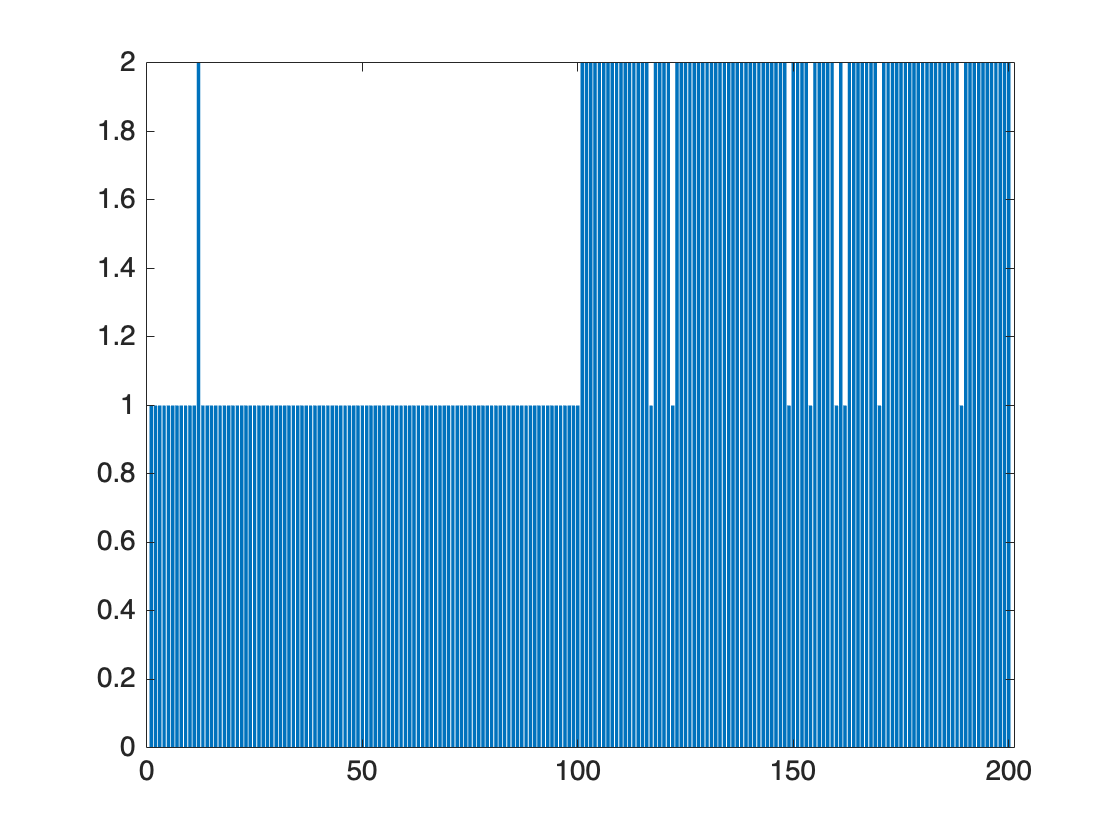


[U_low,~,~] = svd(idx,'econ');
U_top_k = U_low(:,1:K);
Label_sdp = kmeansplus(U_top_k',K)';  % label
bar(Label_sdp)

tic
U_bm = BM_cluster(x_noisy',2);
toc

Elapsed time is 27.981230 seconds.


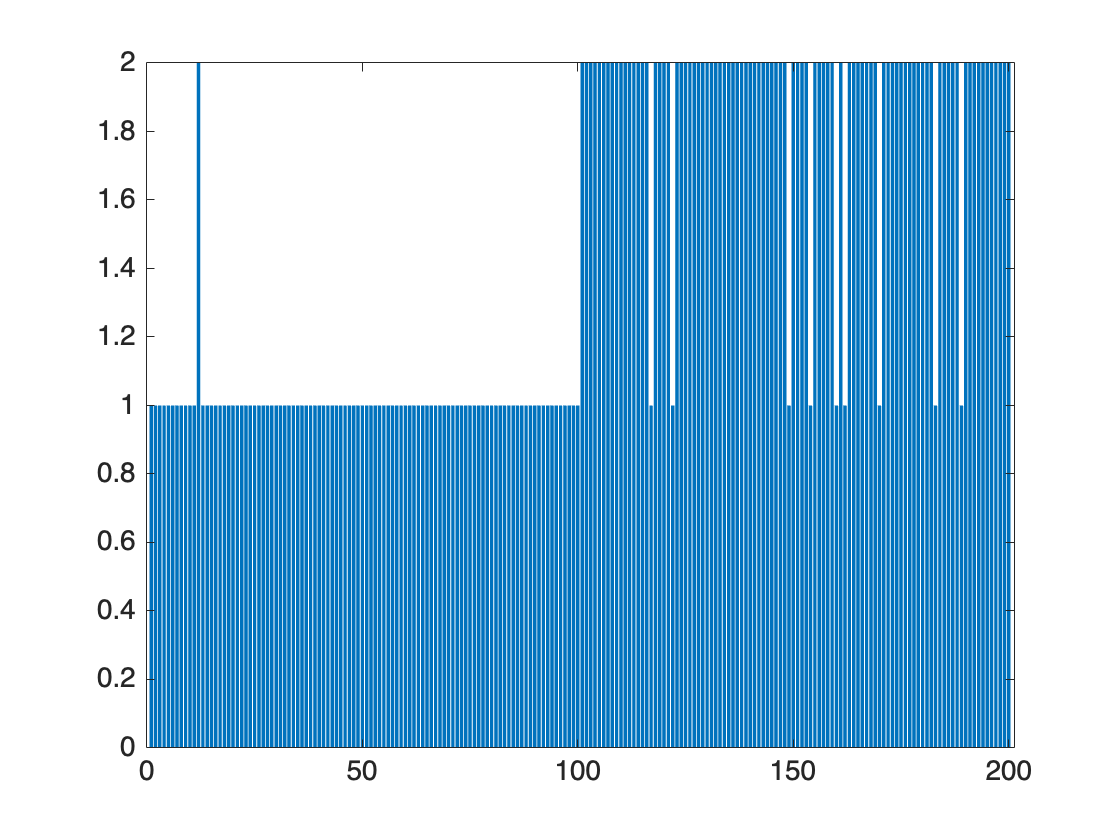

[U_low,~,~] = svd(U_bm,'econ');
U_top_k = U_low(:,1:K);
Label_bm = kmeansplus(U_top_k',K)';  % label
bar(Label_bm)